Calculating the sensor data from the realsense camera.

In the case of simplifying the data, we assume we get a single point in space, that is described with spherical coordinates, that is as a distance to the sensor, and a degree of the x-axis and a degree of the z-axis.


$$\rho \left(\mathrm{rho}\right)\;=\mathrm{distance}\;\mathrm{to}\;\mathrm{the}\;\mathrm{point}\;\mathrm{from}\;\mathrm{Origo}$$



$$\theta \left(\mathrm{theta}\right)=\mathrm{angle}\;\mathrm{between}\;\mathrm{the}\;\mathrm{positive}\;x-\mathrm{axis}\;\mathrm{and}\;\mathrm{the}\;\mathrm{line}\;\mathrm{segment}\;\mathrm{OP}\left(\mathrm{origo}\;\mathrm{to}\;\mathrm{point}\right)$$



$$\phi \left(\mathrm{phi}\right)=\mathrm{angle}\;\mathrm{between}\;\mathrm{the}\;\mathrm{positive}\;x\;\mathrm{and}\;\mathrm{the}\;\mathrm{line}\;\mathrm{segmetn}\;\mathrm{OP}\left(\mathrm{origo}\;\mathrm{to}\;\mathrm{point}\right)$$



$$\left(x\;y\;z\right)=\left(\rho \;\theta \;\phi \;\right)$$


Before we can start the actual simulation, we need to generate some data. This is done by making up a point in space, with the camera sensor as origo, and converting it to the form the sensor would actually use. Going from rectangular coordinates, to spherical coordinates

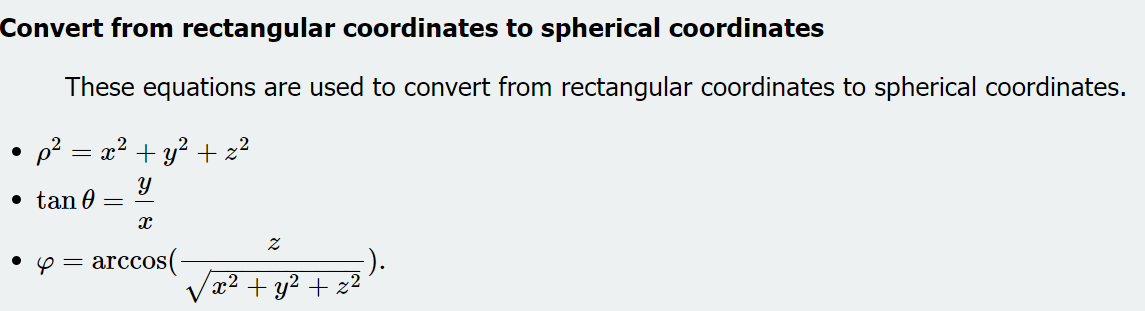

x_ = 10;
y_ = 0.6;
z_ = -0.5;

rho_ = sqrt(x_*x_ + y_*y_ + z_*z_)

rho_ = 10.0305

theta_ = atan(y_/x_)

theta_ = 0.0599

phi_ = acos(z_/(sqrt(x_*x_ + y_*y_ + z_*z_)))

phi_ = 1.6207

First we need to get the placement of the object in rectanuglar coordinates, and then we need to transform it to the base.

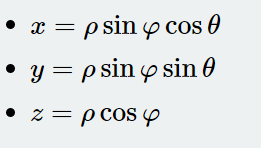

Getting the object in cartesian space:

The values have been found by converting from rectangular coordinates to spherical coordinates, 

rho = rho_

rho = 10.0305

theta = theta_

theta = 0.0599

phi = phi_

phi = 1.6207


x = rho*sin(phi)*cos(theta)

x = 10

y = rho*sin(phi)*sin(theta)

y = 0.6000

z = rho*cos(phi)

z = -0.5000

Defining the transformation from the camera to the base.

Starting with the transformation from the base to the camera, as this is know. And then inversing it.

oPc = [-0.515 0 0.4049]';
oRc = eye(3);

oTc = rt2tr(oRc, oPc);
cTo = inv(oTc);  %This it the transformation matrix between the camera and to the base.

Transforming the sensor values to the base of the robot. 

cPt = [x y z]';

%Using an identity matrix, as there is no rotation wanted.
cTt = rt2tr(eye(3), cPt);

oTt = oTc * cTt

oTt =     1.0000         0         0    9.4850
         0    1.0000         0    0.6000
         0         0    1.0000   -0.0951
         0         0         0    1.0000


Defining the transformation from the base to the base of the arm. 

oPr = [0.237 0 0.1105]';
oRr = eye(3);   %There is no rotation

oTr = rt2tr(oRr, oPr);
rTo = inv(oTr);

Transforming from the base to the base of the arm.

rTt = rTo * oTt

rTt =     1.0000         0         0    9.2480
         0    1.0000         0    0.6000
         0         0    1.0000   -0.2056
         0         0         0    1.0000


distanceToTrashFromBaseOfRobotArm = rTt(2, 4) %Getting the distance along the y-axis

distanceToTrashFromBaseOfRobotArm = 0.6000